% b   = Case9MCSThroughputCalulation240524212808;
% w10 = Case9MCSThroughputCalulationBLERw10Tbler0;
% w50 = Case9MCSThroughputCalulationBLERw50Tbler0;
% w100 = Case9MCSThroughputCalulationBLERw100Tbler0;
% w200 = Case9MCSThroughputCalulationBLERw200Tbler0;
% w1000 = Case9MCSThroughputCalulationBLERw1000Tbler0;
% w20001 = Case9MCSThroughputCalulationBLERw2000Tbler0
% w2001 = Case9MCSThroughputCalulationBLERw2000Tbler1
% w2005 = Case9MCSThroughputCalulationBLERw2000Tbler2;
% w2010 = Case9MCSThroughputCalulationBLERw2000Tbler3;
b = readtable('../Data/Archive/Result_baseline.csv');
w20001 = readtable('../Data/Case9_MCS_ThroughputCalulation_BLERw2000Tbler0.001_240608_153903.csv');
w2001 = readtable('../Data/Case9_MCS_ThroughputCalulation_BLERw2000Tbler0.01_240603_133217.csv');
w2005 = readtable('../Data/Case9_MCS_ThroughputCalulation_BLERw2000Tbler0.05_240604_085504.csv');
w2010 = readtable('../Data/Case9_MCS_ThroughputCalulation_BLERw2000Tbler0.1_240605_171830.csv');

% 

b = add_rate_column_table(b);
w20001 = add_rate_column_table(w20001);
w2001 = add_rate_column_table(w2001);
w2005 = add_rate_column_table(w2005);
w2010 = add_rate_column_table(w2010);

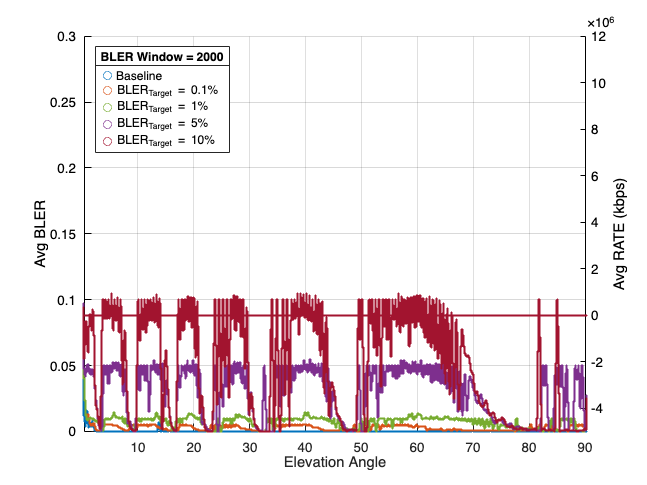

% blue = [0 0.4470 0.7410] 
% orange = [0.8500 0.3250 0.0980] 
% purp = [0.4940 0.1840 0.5560]	 
% green = [0.4660 0.6740 0.1880]	 
% Red = [0.6350 0.0780 0.1840]

grid on
lag = 1500;
colororder({'k','k'})
yyaxis left
hold on
% wavg10 = movavg(w10.BLER,'simple',lag);
% wavg50 = movavg(w50.BLER,'simple',lag);
% wavg100 = movavg(w100.BLER,'simple',lag);
% wavg200 = movavg(w200.BLER,'simple',lag);
% wavg1000 = movavg(w1000.BLER,'simple',lag);
wavg200b = movavg(b.BLER,'simple',lag);
wavg20001 = movavg(w20001.BLER,'simple',lag);
wavg2001 =  movavg(w2001.BLER,'simple',lag);
wavg2005 =  movavg(w2005.BLER,'simple',lag);
wavg2010 =  movavg(w2010.BLER,'simple',lag);


scatter(b.eleAnge,wavg200b,1,[0 0.4470 0.7410])
scatter(w20001.eleAnge,wavg20001,1,[0.8500 0.3250 0.0980] )
scatter(w2001.eleAnge,wavg2001,1,[0.4660 0.6740 0.1880] )
scatter(w2005.eleAnge,wavg2005,1,[0.4940 0.1840 0.5560])
scatter(w2010.eleAnge,wavg2010,1,[0.6350 0.0780 0.1840]	)

ylim([0 .3])
xlim([0.5 90])
ylabel("Avg BLER")
xlabel("Elevation Angle")
hold off
hold on
yyaxis right 
lag = 5000;

ravg200b = movavg(b.RATE,'simple',lag);
ravg20001 = movavg(w20001.RATE,'simple',lag);
ravg2001 = movavg(w2001.RATE,'simple',lag);
ravg2005 = movavg(w2005.RATE,'simple',lag);
ravg2010 = movavg(w2010.RATE,'simple',lag);

scatter(b.eleAnge,ravg200b,1,[0 0.4470 0.7410])
scatter(w20001.eleAnge,ravg20001,1,[0.8500 0.3250 0.0980] )
scatter(w2001.eleAnge,ravg2001,1,[0.4660 0.6740 0.1880] )
scatter(w2005.eleAnge,ravg2005,1,[0.4940 0.1840 0.5560])
scatter(w2010.eleAnge,ravg2010,1,[0.6350 0.0780 0.1840]	)

% ylim([-5e6,12e6])
ylabel("Avg RATE (kbps)")
hold off

lgd = legend('Baseline','BLER_{Target} = 0.1%','BLER_{Target} = 1%','BLER_{Target} = 5%','BLER_{Target} = 10%');
lgd.Location = 'northwest';
lgd.Title.String = "BLER Window = 2000";

function data_with_rate = add_rate_column_table(data)
% Adds RATE (kbps) and cumulative throughput columns to a MATLAB table.
%
%   RATE = TBS (bits) / 1000 if BLKErr == 0, else 0
%   CUM_THROUGHPUT = cumulative sum of RATE (kbps)
%
% Example usage:
%   data_with_rate = add_rate_column_table(data);
%
% Input:
%   data - MATLAB table with columns "TBS" and "BLKErr"
%
% Output:
%   data_with_rate - MATLAB table with added columns "RATE" (kbps) and "CUM_THROUGHPUT" (kbps)

% Compute RATE and cumulative throughput
TBS_bits = data.TBS;        % transport block size in bits
BLKErr = data.BLKErr;       % block error indicator
RATE_kbps = (TBS_bits .* (BLKErr == 0)) / 1000; % kbps for successful transmission (BLKErr==0)
cum_throughput_kbps = cumsum(RATE_kbps);        % cumulative throughput (kbps)

% Add new columns to the table
data.RATE = RATE_kbps;
data.CUM_THROUGHPUT = cum_throughput_kbps;

% Return updated table
data_with_rate = data;
end